addpath("functions/");
clear

# Simulation

- runnare tantissimo

- animare drive per drive

- manna (stocasticità estraendo n_topple=4 randi sugli active sites e fare find(j==1) per nn_left etc)

- periodic boundary

save_to_file = true;

L = 50;
steps = 10e5;
wait = 10e2;

% Model to run
BTW

% Cleanup workspace
clear("nn_u","nn_r", "nn_l","nn_d","d_as","l_as", ...
	"r_as","u_as","i","L_b","count")

% Save to file if the box was checked
if save_to_file; save(sprintf('data/BTW_data_%s.mat',...
		datestr(now,'mm-dd_HH-MM')), ...
		"event_size","z","L","steps"); end

# Post processing and plotting

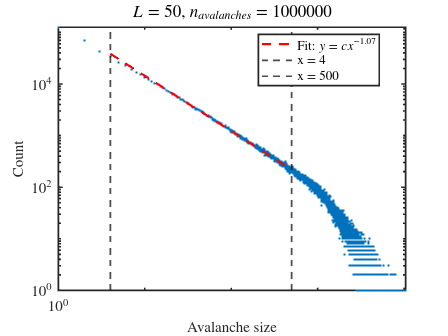

addpath("functions/");

if ~exist('event_size','var'); load("/home/francesco/Documents/UNI/Sistemi complessi/SOC simulation/data/BTW_data_08-22_22-26.mat"); end

[sizes, count] = postprocess_data(event_size);
title = "$L = "+L+"$, $n_{avalanches} = "+steps+"$";
[fig,tau] = plot_avalanches(sizes,count,4,500,title);